Code for backward projection.

clear
mex -v GCC='/usr/bin/g++-6' -R2018a forward_projection.cpp

Building with 'g++'.


MEX completed successfully.


Input variables

img_size = 256;
input_array = single(phantom(img_size));

num_det_pix=367;
det_pix_len=1;  % In mm

img_pix_len_x=1;  % In mm
img_pix_len_y=1;  % In mm

sampling_interval=1;  % In mm
num_views=180;
projection_range=180;  % In degrees

fftw('planner', 'measure');

my_sinogram = forward_projection(input_array, num_det_pix, det_pix_len,...
    img_pix_len_x, img_pix_len_y, sampling_interval, num_views,...
    projection_range);

thetas = (0:(num_views-1)) * (projection_range/num_views);
sinogram = radon(input_array, thetas);

my_recon = filtered_backprojection_matlab(my_sinogram,...
    img_size, img_size, img_pix_len_x, img_pix_len_y,...
    det_pix_len, sampling_interval, projection_range);

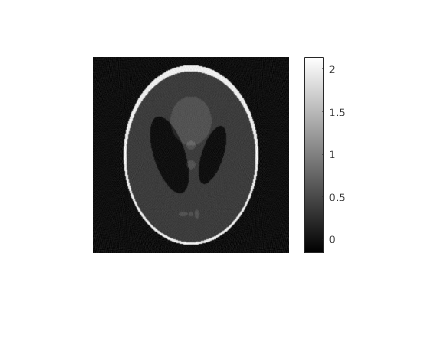

imshow(my_recon, [])
colorbar()

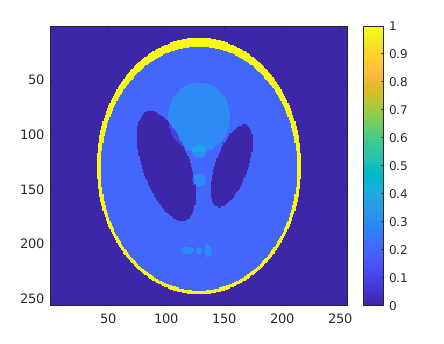

imagesc(input_array)
colorbar()

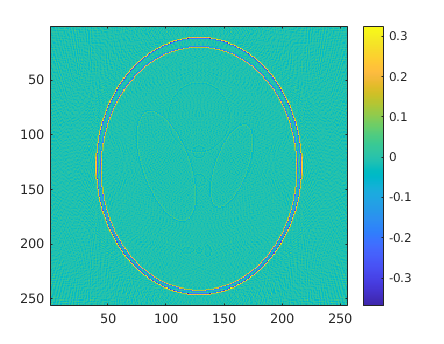

imagesc(my_recon/2 - input_array)
colorbar()

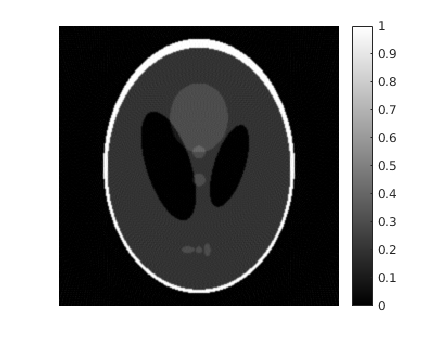

recon = iradon(sinogram, thetas);
imshow(recon)
colorbar()

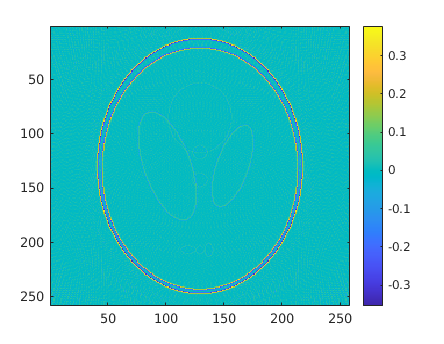

imagesc(recon - padarray(input_array, [1, 1], 0, 'both'))
colorbar()

orig = @() iradon(sinogram, thetas)

orig = function_handle with value:
    @()iradon(sinogram,thetas)


my_matlab = @() filtered_backprojection_matlab(my_sinogram,...
    img_size, img_size, img_pix_len_x, img_pix_len_y,...
    det_pix_len, sampling_interval, projection_range);

orig_time = timeit(orig)

orig_time = 0.0116

mat_time = timeit(my_matlab)

mat_time = 0.1146

disp(orig)

    @()iradon(sinogram,thetas)



disp(mat_time)

    0.1146

